clear;clc;close all;
global SourceFolder InitDate EndDate
InitDate = '1-Jan-1921';
EndDate='now';%'07-Aug-2019';%
SourceFolder='/Users/oristav/Library/CloudStorage/Dropbox/Library/Code/OriFin/#MatCode/Investments Analytics';
cd (SourceFolder);% cd ([SourceFolder,'#MatCode/Investments Analytics']);

addpath("Functions/")
addpath("Functions/Mine")
addpath("Functions/Process")
addpath("Functions/Visualize")

# Stocks periodical analysis - Comparison

Status = "Mined"

Status = "Cleaned"

Status = "Processed"

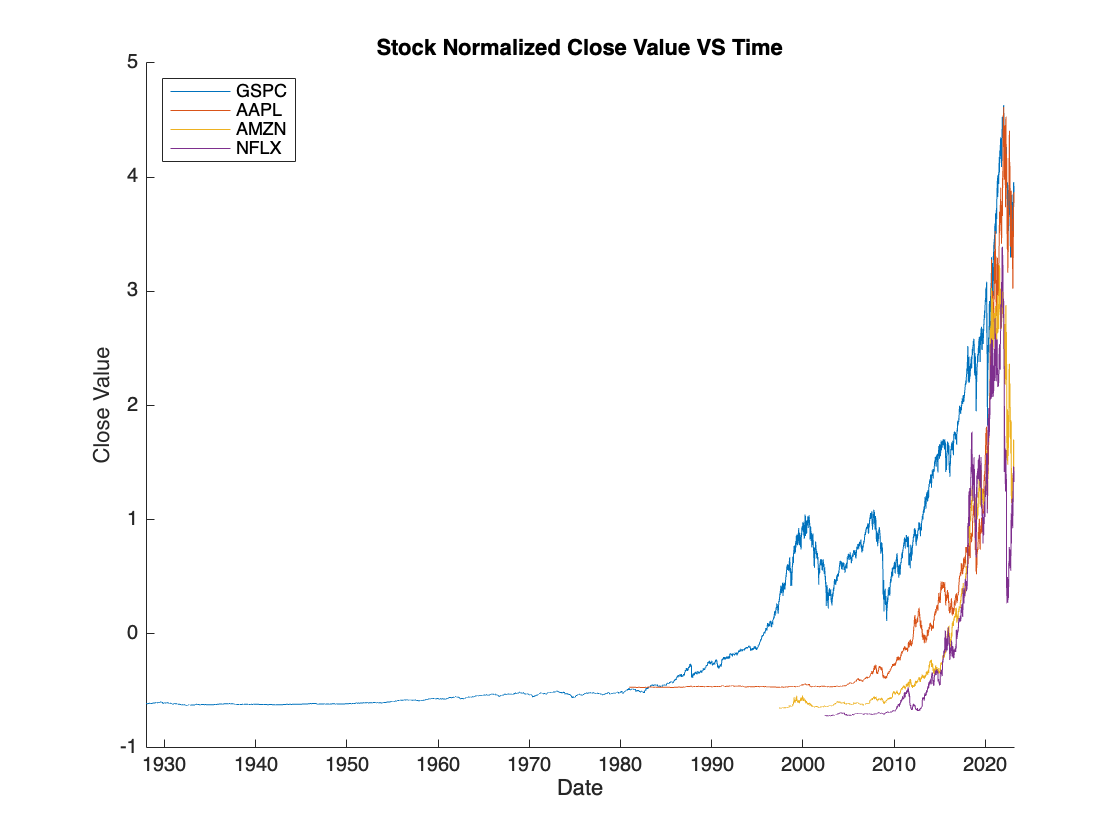

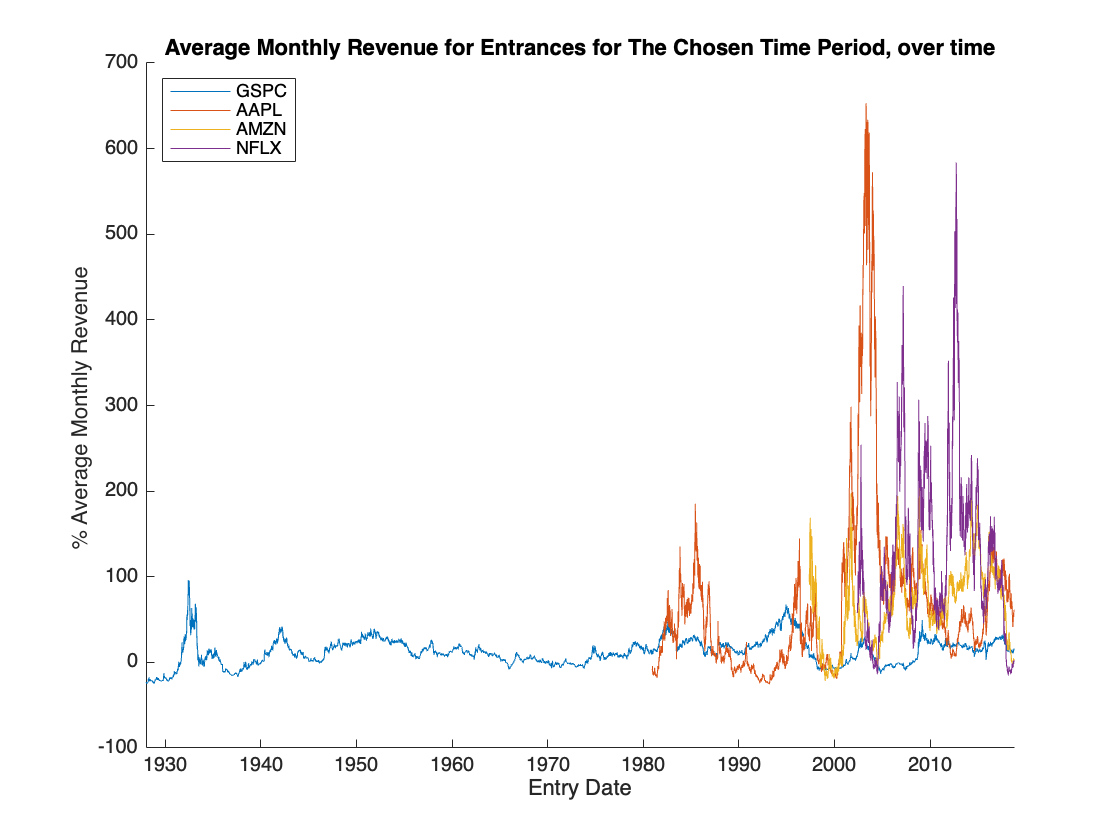

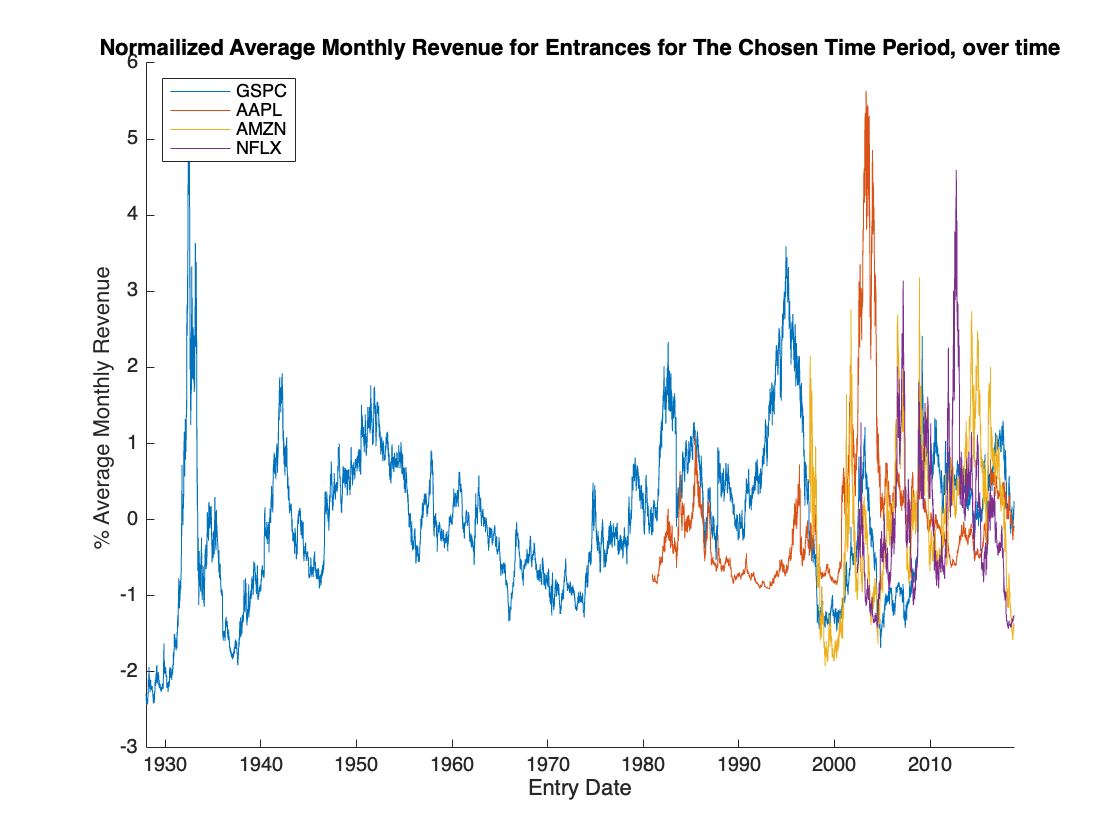

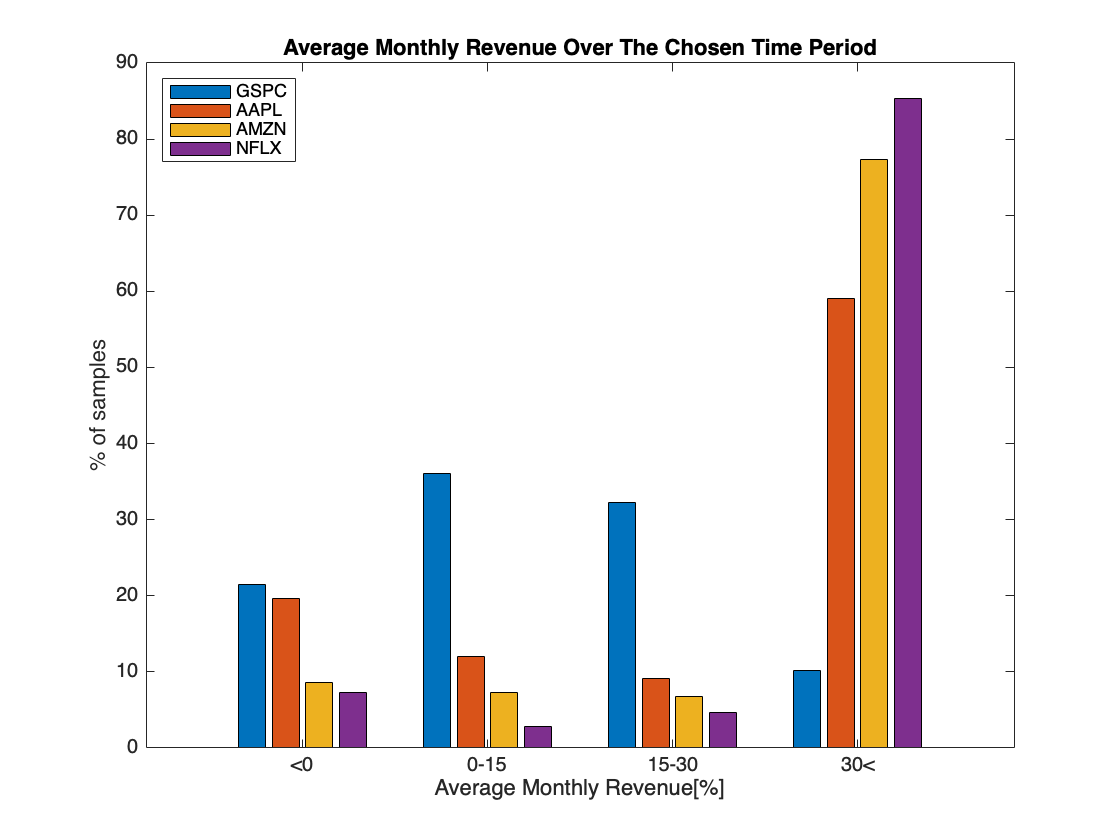

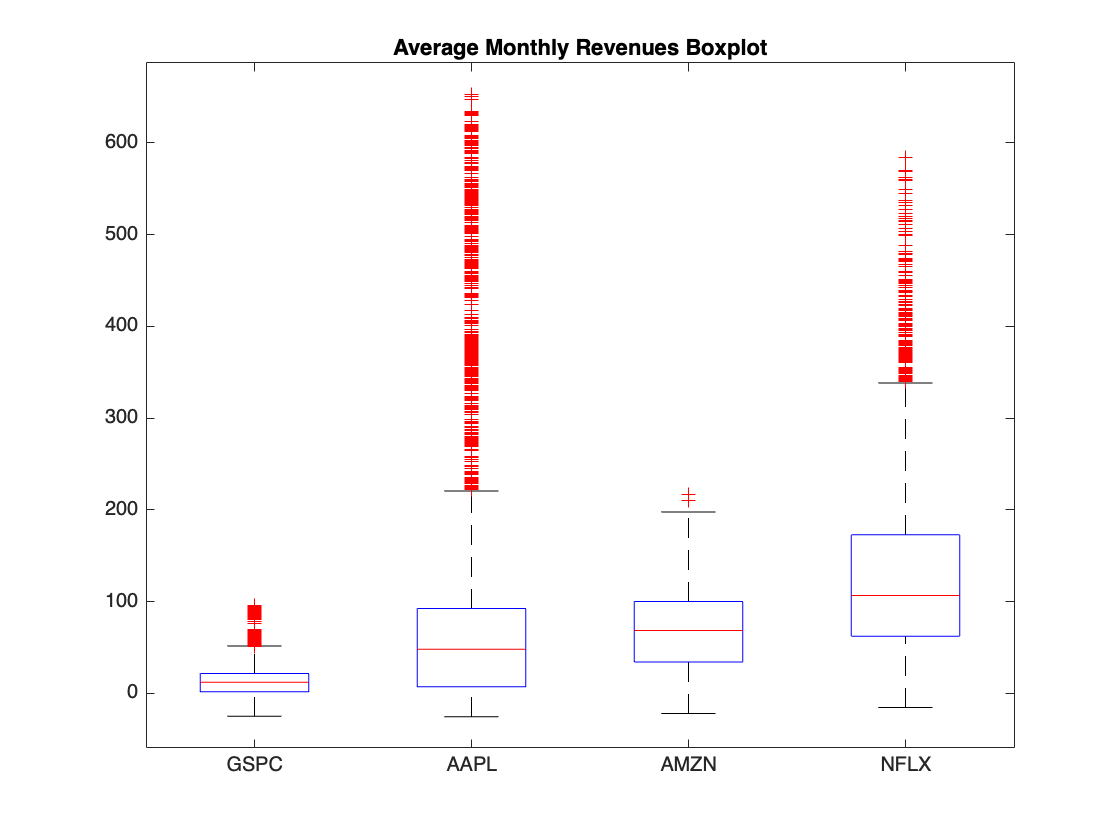

ProcessedTable = 4×10 table
              Min       Mean      STD      Samples    Duration     Max       Med           Mstock               Dstock                      RangesCount             
            _______    ______    ______    _______    ________    ______    ______    ________________    __________________    ____________________________________

    GSPC    -24.895    12.459    15.366     22803      33158      96.136    12.073    {22803×2 double}    {22803×1 datetime}    21.532    36.052    32.276    10.139
    AAPL    -25.568    69.565    103.53      9541      13817      653.12    48.214    { 9541×2 double}

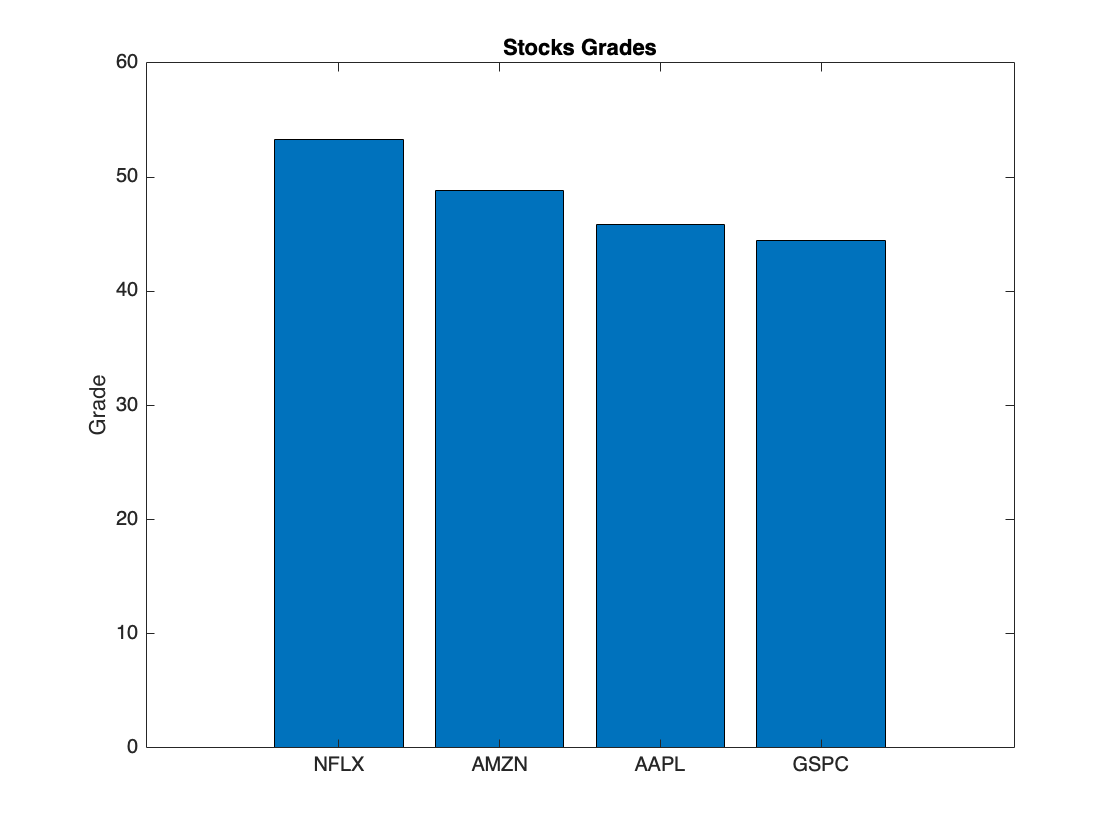

ans = 4×8 table
            Min    Mean    STD    Samples    Duration    Max    Med    Superposition
            ___    ____    ___    _______    ________    ___    ___    _____________

    NFLX    89      89     38        2           2       64     89        53.286    
    AMZN    63      39     63       38          38       38     63        48.857    
    AAPL     2      63      2       63          63       89     39        45.857    
    GSPC    38       2     89       89          89        2      2        44.429    


Status = "Visualized"

StocksCategory="BigTech";
InvestmentDuration=3;%Years
ImportMat.Mine=false;
ImportMat.Clean=false;
ImportMat.Process=false;

AnalysisName="17_02_23";%replace(string(datetime('now')),":","_")
tic
struct=Execute(StocksCategory,InvestmentDuration,ImportMat,AnalysisName);

toc

Elapsed time is 23.281042 seconds.


% clear AnalysisName StocksCategory InvestmentDuration ...
%     SourceFolder InitDate EndDate ImportMat